# Speeding up electrical simulations with Parallel Computing (Normal and Accelerator Mode)

Copyright 2023-2024 The MathWorks, Inc.

### Overview

Parallel Simulation can be used everywhere, where iterations are order independent. This is the case for 

- parameter sweeps 

- monte-carlo analysis

- gradient calculation within local optimization problem

- parallel calculations during global optimiuzation problem

- model testing (Simulink Test)

In all these cases parallel computing can be used to execute the model on multiple **cores** or an **parallel workers within a cluster**. 

The **parsim** **/ parfor **command will be used, in combination with **Fast Restart, ** **Simulation Modes** and **Simulink.SimulationInput** objects.

### Fast Restart

- Fast Restart will prevent model checking and simplifies initialization once this has been done during the first run

- Make sure Simulink parameters are tunable (default) and Simscape parameters are run-time parameters if and only if they have to be tuned. Setting all Simscape parameters as run-time parameters will slow down the simulation.

- Using the Simulink.SimulationInput object you have to use **'UseFastRestart' **within the parsim command  instead on 'FastRestart'.

- Fast Restart is not supported in Rapid Accelerator Mode (see other script)

- Fast Restart also works with Startup Activation Variants

### Simulation Modes

- Normal Mode and Accelerator Mode models can use this script, Rapid Accelerator Mode will require another script because the workflow is slightly different.

- Accelerator Mode brings most benefits if large Simulink section or Specialized Power Systems sections in the model

### **Simulink.SimulationInput** Object

- A** Simulink.SimulationInput** object should be used for setting up all parameter, input data or startup acitivation variants by using the setVariable method (supports Fast Restart).

- The setting from the Simulink.SimulationInput object temporarily overwrite the model variables only.

- Specific pre/post simulation functions can be defined as callbacks.

### Number of effectively used cores

- Number of effectively used cores is the number of physical cores.

## Workflow

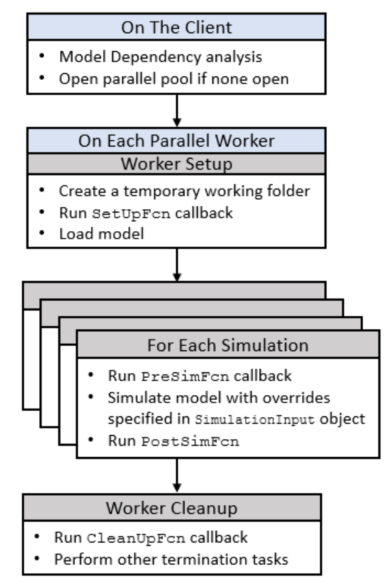

### Step 1: Open the model

Path = pwd;

example = 'simscapeelectrical/SmartphoneBatteryChargingExample';
openExample(example);
mdl = bdroot;
demoPath = pwd;
addpath(demoPath); % needed for parfor

cd(Path);

Save model under new name

save_system(mdl,[Path,'\',mdl,'_local']);
mdl = [mdl,'_local'];

Setup result logging for logged signals, because interactive scopes will not work with parallel simulations

Disable Statistics logging, because it is not supported with parallel simulations

set_param(mdl,'SimscapeLogType','none');
set_param(mdl,'SimscapeLogSimulationStatistics','off');
set_param(mdl,'SaveTime','off');
set_param(mdl,'SaveOutput','off');
set_param(mdl,'SignalLogging','on');
set_param(mdl,'ReturnWorkspaceOutputs','on');

### Step 2: Create a parallel pool

Check the number of used physical cores for parallelization

If Hyper Threading is enable in BIOS, not all logical cores can be used with Parallel Computing Toolbox.

nCores = feature('numcores')

nCores = 12

Select the number of cores you want to use

parallelMode = "4";
if isstring(parallelMode)
    parallelMode = str2double(parallelMode);
end
    
if isempty(gcp('nocreate'))
    parpool(parallelMode,'IdleTimeout',120);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


### Step 3: Choose the Simulation Mode

simMode ="accelerator";
set_param(mdl,'SimulationMode',simMode);
save_system(mdl);

### Step 4: Create Input and Parameter Sets

All input or parameter combinations that should be used during parameter sweep should be set up in advance in a Simuink.SimulationInput object.

Make sure all these parameters use variables (not fixed values) and that those variables are either 

- Tunable Parameters (if in Simulink) or 

- Runtime Parameters (if in Simscape). 

Per default Simulink parameters are tunable.

Set Simscape parameter as runtime parameter to support fast restart

set_param([mdl,'/Battery/battery/Battery',newline,'(Table-Based)'],'AH_conf','runtime');
save_system(mdl);

Perturb the charging parameters. 

charging_CV_vals = [5:8];
charging_CC_vals = [3.65,3.75];
charging_SW = 3.6;
cellAhr_vals = [4.1,5.6];

num_charging_CV_vals = length(charging_CV_vals);
num_charging_CC_vals = length(charging_CC_vals);
num_cellAhr_vals = length(cellAhr_vals);

clear in;
numSim = num_charging_CV_vals*num_charging_CC_vals*num_cellAhr_vals;
in(1:numSim) = Simulink.SimulationInput(mdl);

idx = 1;
for iAhr = 1:num_cellAhr_vals
    for iCC = 1:num_charging_CC_vals
        for iCV = 1:num_charging_CV_vals
            % Use setVariable to specify a new value for a variable during
            % simulations, SetBlockParameters will not be supported by
            % Fast Restart
            in(idx) = in(idx).setVariable('charging_CV', charging_CV_vals(iCV));
            in(idx) = in(idx).setVariable('charging_CC', charging_CC_vals(iCC));
            in(idx) = in(idx).setVariable('cellAhr', cellAhr_vals(iAhr));
            idx = idx + 1;
        end
    end
end

### Step 5: Execute Simulations

Use the parsim function to execute the simulations in parallel. The array of SimulationInput objects,called 'in', created in the last step is passed into the parsim function as the first argument. Store the simulation output data in a variable, called 'out', whose value is an array of Simulink.SimulationOutput objects. Each SimulationOutput object contains the logged signal along with the SimulationMetadata. When running multiple simulations using parsim, errors are captured so that subsequent simulations can continue to run. Any errors would show up in the ErrorMessage property of the SimulationOutput object.

The UseFastRestart option has to be set here within the parsim command, because the models run on different cores, instead of the classical FastRestart option for a single run.

tic;
out = parsim(in,'UseFastRestart','on','TransferBaseWorkspaceVariables','on', ...
                'ShowSimulationManager','on','ShowProgress','on');

[17-Sep-2024 13:36:57] Checking for availability of parallel pool...
[17-Sep-2024 13:36:57] Starting Simulink on parallel workers...
[17-Sep-2024 13:37:05] Configuring simulation cache folder on parallel workers...
[17-Sep-2024 13:37:05] Transferring base workspace variables used in the model to parallel workers...
[17-Sep-2024 13:37:05] Total size of base workspace variables to send to parallel workers is 1.30 MB.
[17-Sep-2024 13:37:07] Loading model on parallel workers...
[17-Sep-2024 13:37:23] Running simulations...
[17-Sep-2024 13:39:02] Cleaning up parallel workers...


Measure the elapsed time

toc

Elapsed time is 134.390663 seconds.


**Normal Mode, Fast Restart, 4 cores                                                        Accelerator Mode, Fast Restart, 4 cores**

 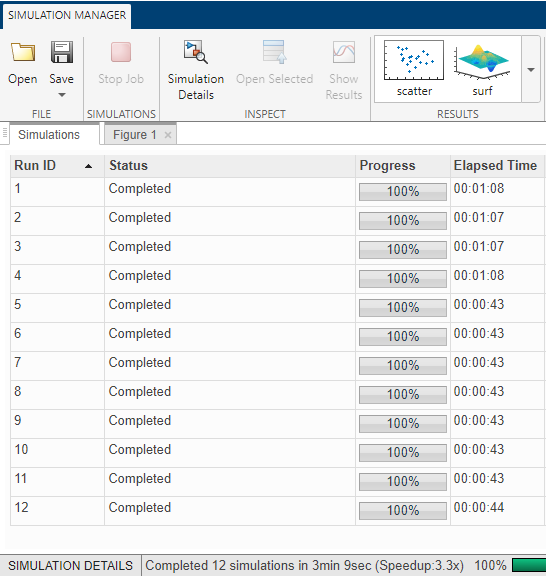       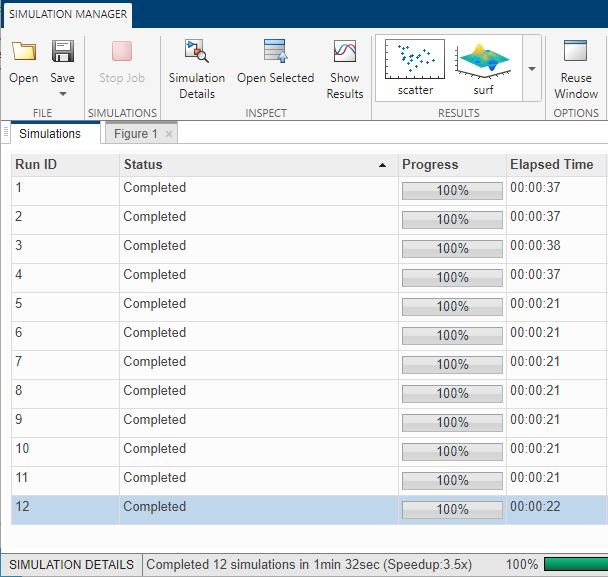

### Step 5: Plot Results

Plot the engine idle speed with respect to time for different parameter values and inputs. The output is logged in the array format and can be accessed from the SimulationOutput object.

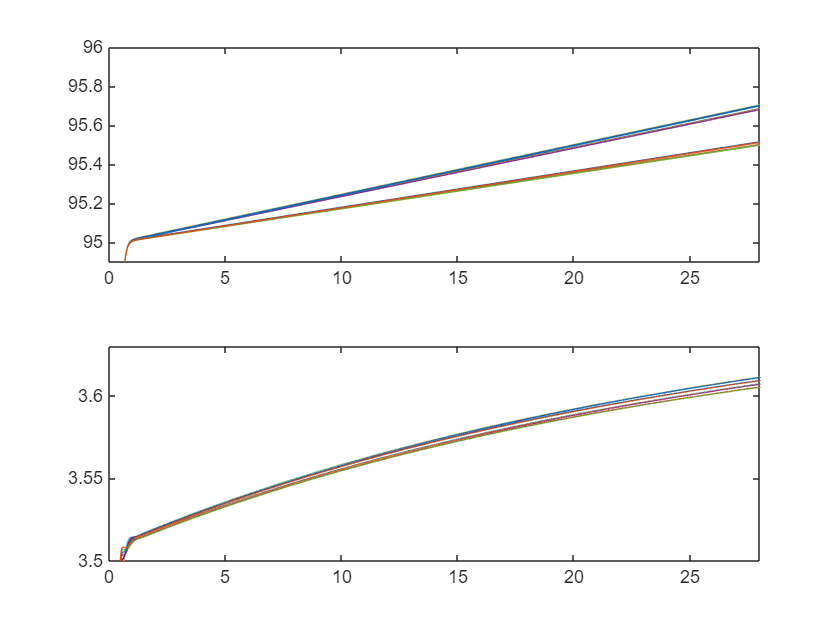

for i = 1:numSim
    simOut = out(i);
    t   = simOut.logsout{1}.Values.Time;
    SOC = simOut.logsout{1}.Values.Data;
    Vmeas   = simOut.logsout{2}.Values.Data;
    subplot(2,1,1);
    plot(t, SOC);
    axis(gca,[0,28,94.9,96])
    hold on;
    subplot(2,1,2);
    plot(t,Vmeas);
    axis(gca,[0,28,3.5,3.63])
    hold on;
end

### Step 6: Alternatively run the simulation with parfor and sim command

Instead of parsim also parfor can be used with the same simulation input object.

The maximum speed can only be reached by using a packaging concept which means by iterating over of all cores within the parfor command and equally distributing all runs within the sim command by assiging parameterization in a vectorized form.

The simulation manager is not supported here.

clear out;

tic;
nSerialIter = ceil(length(in)/parallelMode);
parfor i=1:parallelMode        
    out(i,:) = sim(in((i-1)*nSerialIter+1:i*nSerialIter),'UseFastRestart','on');
end

[17-Sep-2024 13:40:07] Running simulations...
[17-Sep-2024 13:40:07] Running simulations...
[17-Sep-2024 13:40:07] Running simulations...
[17-Sep-2024 13:40:07] Running simulations...
[17-Sep-2024 13:40:29] Completed 1 of 4 simulation runs
[17-Sep-2024 13:40:29] Completed 1 of 4 simulation runs
[17-Sep-2024 13:40:29] Completed 1 of 4 simulation runs
[17-Sep-2024 13:40:29] Completed 1 of 4 simulation runs
[17-Sep-2024 13:40:42] Completed 2 of 4 simulation runs
[17-Sep-2024 13:40:42] Completed 2 of 4 simulation runs
[17-Sep-2024 13:40:42] Completed 2 of 4 simulation runs
[17-Sep-2024 13:40:42] Completed 2 of 4 simulation runs
[17-Sep-2024 13:40:53] Completed 3 of 4 simulation runs
[17-Sep-2024 13:40:53] Completed 3 of 4 simulation runs
[17-Sep-2024 13:40:53] Completed 3 of 4 simulation runs
[17-Sep-2024 13:40:54] Completed 3 of 4 simulation runs
[17-Sep-2024 13:41:05] Completed 4 of 4 simulation runs
[17-Sep-2024 13:41:05] Completed 4 of 4 simulation runs
[17-Sep-2024 13:41:05] Completed

Measure the elapsed time

toc

Elapsed time is 59.496618 seconds.


out = reshape(out,length(in),1);

### Step 7: Plot Results

Plot the engine idle speed with respect to time for different parameter values and inputs. The output is logged in the array format and can be accessed from the SimulationOutput object.

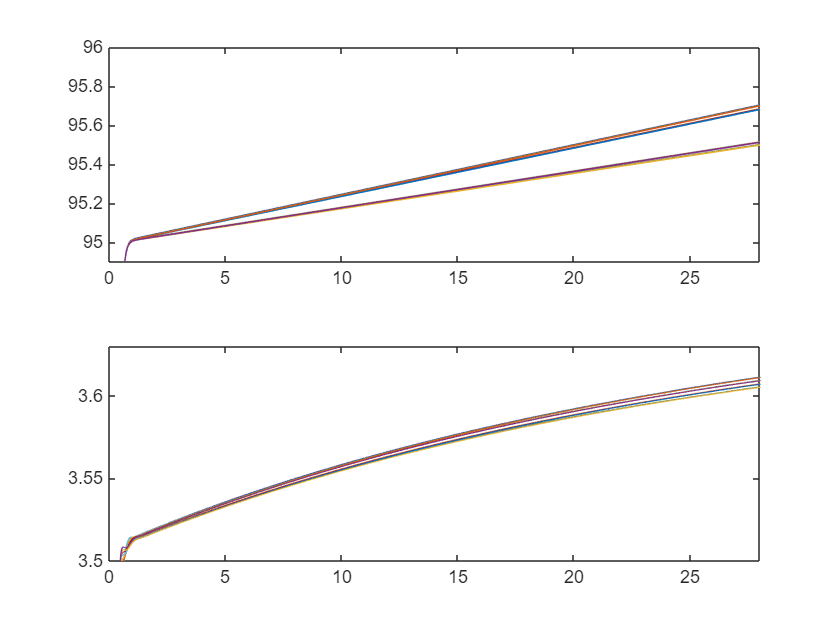

for i = 1:numSim
    simOut = out(i);
    t   = simOut.logsout{1}.Values.Time;
    SOC = simOut.logsout{1}.Values.Data;
    Vmeas   = simOut.logsout{2}.Values.Data;
    subplot(2,1,1);
    plot(t, SOC);
    axis(gca,[0,28,94.9,96])
    hold on;
    subplot(2,1,2);
    plot(t,Vmeas);
    axis(gca,[0,28,3.5,3.63])
    hold on;
end

### Step 8: Stop the parallel cores if not needed any longer and clear the Simulation Input Object  

rmpath(demoPath); 
delete(gcp);

Parallel pool using the 'Processes' profile is shutting down.


clear in;
close_system(mdl);